# Relatório de Atividade - Estimação de parâmetros

*Débora Nunes Pinto de Oliveira*

*Prof. Antonio Marcus, Análise e Projeto de Sistemas de Controle 21.1*

*19 de abril de 2021*

Esse documento tem por objetivo descrever a identificação de modelos pelo método dos mínimos quadrados. Esse algoritmo determina uma estimação dos parâmetros do modelo e é adequado para ***processos não-lineares ou variantes no tempo***. 

## **Fundamentação Teórica**

O modelo de uma planta é construído conforme dados experimentais [1]. Isto é, a identificação de um processo é desenvolvida segundo uma relação matemática entre as entradas e saída coletadas. Para controle adaptativo, a entrada da planta é originada via *feedback* e não pode ser determinada unicamente [2]. Portanto, deve-se estimar os parâmetros do modelo simulado para o comportamento mais próximo do processo real. Um desses algoritmos de estimação é nomeado método dos mínimos quadrados.

A relação de entrada $u(t)$e saída $y(t)$ de um sistema discreto pode ser dada por:


$$y(t) + a_1y(t-1) + ... + a_ny(t-n) = b_1u(t-1)+...+b_mu(t-m)$$


A qual pode ser reescrita como:


$$\hat{y}(t|\theta) = - a_1y(t-1) - ... - a_ny(t-n) + b_1u(t-1)+...+b_mu(t-m) = \varphi^T(t)\theta$$


para $\varphi(t) = [-y(t-1)\; ...-y(t-n)\ u(t-1)\; ...\; u(t-m)]^T$ e $\theta = [a_1\; ...\; a_n\ b_1\; ...\; b_m]^T$. com o intuito de encontrar o menor erro entre o processo real e o estimado, deve-se encontrar o mínimo da função de custo $V(\theta,t)$, sendo


$$V(\theta,t)=\frac{1}{2}\sum_{k=1}^t \big(y(k)-\hat{y}(k)\big)^2 = \frac{1}{2}\sum_{k=1}^t \big(y(k)-\varphi^T(k)\theta\big)^2$$


Para encontrar $\min V(\theta,t)$, encontra-se $\hat{\theta}$ tal que $\partial V(\hat{\theta},t)/\partial\theta=0$. Dessa forma:


$$\sum_{k=1}^t \varphi(k)\big(y(k)-\varphi^T(k)\hat{\theta}\big) =0 \rightarrow \sum_{k=1}^t  \varphi(k)y(k) = \sum_{k=1}^t  \varphi(k)\varphi^T(k)\hat{\theta}$$



$$\therefore \hat{\theta} = \Big[\sum_{k=1}^t\varphi(k)\varphi^T(k)\Big]^{-1}\sum_{k=1}^t\varphi(k)y(k)  = P(t) \sum_{k=1}^t\varphi(k)y(k)$$


Logo, é evidente que $P(t)$ deve ser positiva definida. Nesse estudo, será generalizado $\varphi(t) = [\varphi_1(t)\ ...\ \varphi_{n+m}(t)]^T$ para $\varphi_i(t)$ uma função das entradas e saídas do processo. 

## Desenvolvimento

Os controladores propostos foram construídos e simulados utilizando blocos no Simulink. As estratégias adotadas seguem a apresentação citada na Seção 1. Primeiramente, serão apresentados os exercícios resolvidos. Por fim, serão discutidas as questões propostas.

### Exemplo 1: Mínimos quadrados em processos invariantes no tempo

Considere o sistema tal que $\varphi(t) = [1\ u(t)\ u^2(t)]^T$ e $\theta=[b_0\ b_1 \ b_2]^T$ para $y(t)=\varphi^T(t)\theta_0+e(t)$, sendo $e(t)$um ruído gaussiano com desvio padrão $0.1$. A expressão de $\hat{\theta}$ é adaptada para:


$$\hat{\theta}= P(t) \sum_{k=1}^t\varphi(k)[\varphi^T(k)\theta_0+e(k)]$$


Logo, o erro $\tilde{\theta} = \hat{\theta}-\theta_0$ é dado por:


$$\tilde{\theta}= P(t) \sum_{k=1}^t\varphi(k)e(k)$$


Se $e(t)$ é um ruído gaussiano de média nula, $u$ e $y$ variáveis determinísticas e $E$ o valor esperado, obtém-se que


$$E\tilde{\theta}= P(t) \sum_{k=1}^t\varphi(k)Ee(k)=0$$


Logo, a estimativa de $\hat{\theta}$ pelo método de mínimos quadrados rejeita ruídos gaussianos na medição da saída $y(t)$. 

Essa questão tem por objetivo discutir qual a ordem de $\hat{\theta}
$ do modelo estimado mais se adequa à planta simulada. É esperado que com o aumento da ordem, a curva do modelo identificado se aproxime do processo real até atingir um erro mínimo. Foram realizados 4 experimentos variando a ordem da matriz $\hat{\theta}$ entre 1 e 4. O valor real de $y(t)$ e estimado $\hat{y}(t)$ para cada modelo estão ilustrados na Figura 1.

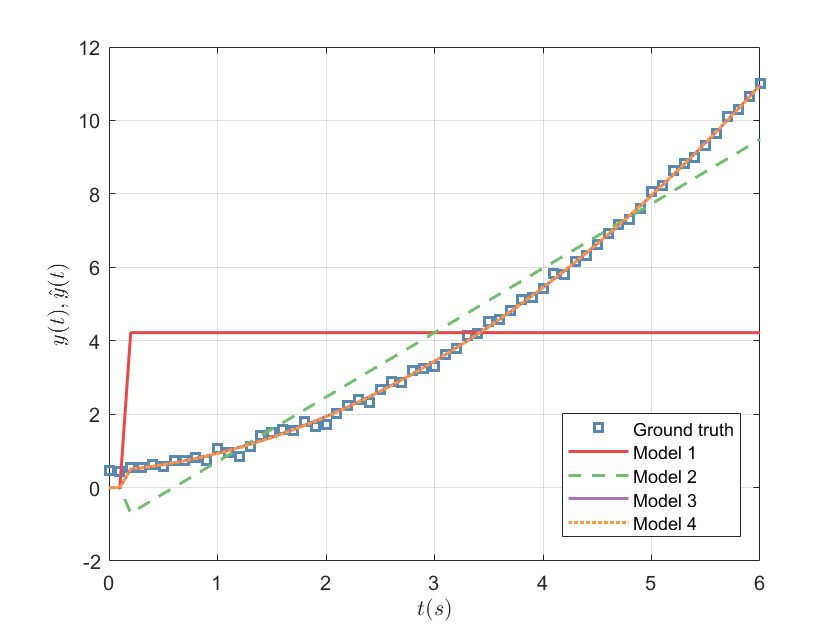

ex01

***Figura 1: ***$y(t)$* e *$\hat{y}(t)$* para *$\hat{\theta}$* um vetor de ordem 1 a 4.*

Para os modelos para ordem de 2 ou 3 de  $u(t)$ em $\varphi$, o desvio padrão entre $y(t)$ e $\hat{y}(t)$ é aproximadamente $0,13$. Para $\varphi = [1\ u(t)]$ e $\varphi = [1]$, o desvio padrão entre $y(t)$ e $\hat{y}(t)$ é $0,65$ e $10$, respectivamente. Analisando esses resultados, é evidente que o aumento da ordem da matriz $\theta$ aproxima $\hat{y}$ de $y$ até atingir um erro mínimo. Observando a Figura 1, fica claro que o erro gaussiano $e(t)$ é rejeitado pela estimativa de mínimos quadrados.

### Exemplo 3: Mínimos quadrados em processo não-linear

A matriz $R = P^{-1}(t)$ pode ser reescrita como:


$$P^{-1}(t) = \sum_{k=1}^{t-1}\varphi(k)\varphi^T(k) + \varphi(t)\varphi^T(t)  = P^{-1}(t-1)+\varphi(t)\varphi^T(t) $$
 

Considerando que

 
$$\hat{\theta} (t-1)= P(t-1) \sum_{k=1}^{t-1}\varphi(k)y(k) \therefore \sum_{k=1}^{t-1}\varphi(k)y(k) = P^{-1}(t-1) \hat{\theta} (t-1)$$


Substituindo $P^{-1}$:


$$P^{-1}(t-1) \hat{\theta} (t-1) = \big[P^{-1}(t)-\varphi(t)\varphi^T(t) \big]\hat{\theta} (t-1) $$


Logo 


$$\hat{\theta} (t)= P(t) \sum_{k=1}^{t}\varphi(k)y(k) = P(t) \Bigg[\sum_{k=1}^{t-1}\varphi(k)y(k)+\varphi(t)y(t)\Bigg]  = P(t)\big[P^{-1}(t)-\varphi(t)\varphi^T(t) \big]\hat{\theta} (t-1) + P(t)\varphi(t)y(t)$$



$$\therefore \hat{\theta}(t) = \hat{\theta}(t-1)-P(t)\varphi(t)\varphi^T(t)\hat{\theta}(t-1) + P(t)\varphi(t)y(t) = \hat{\theta}(t-1)+K(t)\varepsilon(t)$$


para $K(t) = P(t)\varphi(t)$ e $\varepsilon = y(t)-\varphi^T(t)\hat{\theta}(t-1)$. Dessa forma, $\hat{\theta}(t)$depende apenas da última amostra e é, portanto, adequado para aplicação no laço de realimentação de um controlador adaptativo. É importante destacar a necessidade de definir o valor $\hat{\theta}(0)$ e $P(0)$.

Considerando que, para matrizes quadradas $A$, $C$ e $C^{-1}+DA^{-1}B$ não singulares, a matriz inversa de $A+BCD$ é


$$(A+BCD)^{-1} = A^{-1}-A^{-1}B(C^{-1}+DA^{-1}B)^{-1}DA^{-1}$$


para $A=P^{-1}(t-1)$, $B=\varphi(t)$, $C=I$e $D=\varphi^T(t)$, encontra-se que:

'

Logo, para $K(t) = P(t)\varphi(t)$, obtém-se:


$$K(t) = P(t)\varphi(t) = P(t-1)\varphi(t)\big[I+\varphi^T(t)P(t-1)\varphi(t)\big]^{-1}$$


É evidente o cálculo de uma matriz inversa. Porém, como $\varphi^T(t)P(t-1)\varphi(t)$ é um escalar, a inversão é simples e nunca indefinida, uma vez que $I=1$. Essa formulação dos métodos dos mínimos quadrados é nomeada recursivo (RLS).

Considere o sistema não linear $\varphi(t) = [-y(t)\ u(t)\ \sin{u(t)}]^T$ e $\theta=[a\ b_1 \ b_2]^T$ para $y(t)=\varphi^T(t-1)\theta_0$. Como os parâmetros são lineares, a estimativa de $\hat{\theta}$ pode ser obtida conforme o método dos mínimos quadrados recursivo. O valor real de $y(t)$ e estimado $\hat{y}(t)$ para cada modelo estão ilustrados na Figura 2.

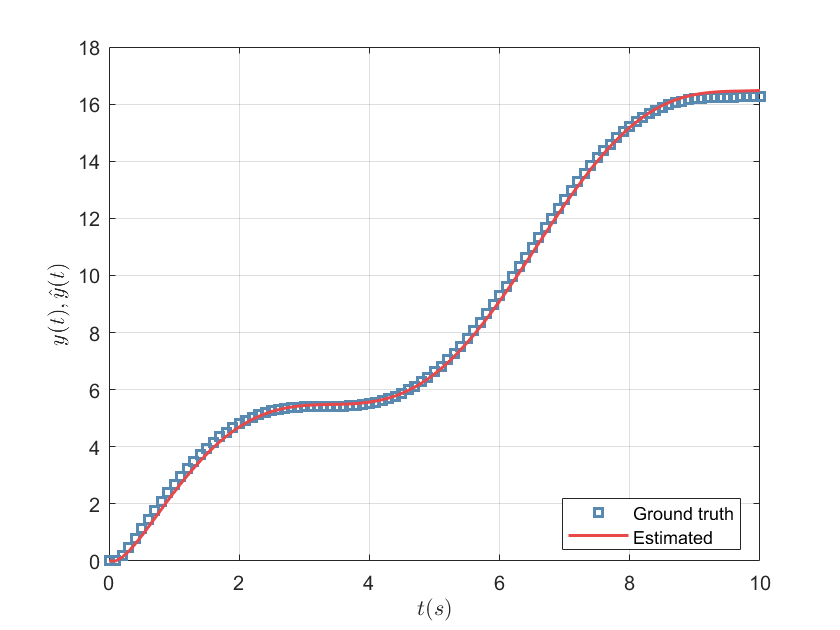

ex03

***Figura 2: ***$y(t)$* e *$\hat{y}(t)$* para *$\hat{\theta}$* um vetor de ordem 3.*

Conforme ilustrado na Figura 2, o modelo não linear é corretamente estimado empregando RLS. Como os parâmetros são lineares, é possível construir um vetor $\theta$ tal que $y(t)=\varphi^T(t)\theta_0$. O desvio padrão entre a função estimada $\hat{y}$ e a real $y$ é:

sqrt(mean((z-y).^2))

ans = 0.1493

### Exemplo 5: Função degrau como entrada de um sistema

Para analisar a persistência de um sinal de excitação $u$, considera-se a matriz $C_n$ tal que:


$$C_n = \lim_{t\rightarrow\infty}\frac{P^{-1}(t)}{t}=$$

$$\left\lbrack \begin{array}{cccc}
c\left(0\right) & c\left(1\right) & \cdots  & c\left(n-1\right)\\
c\left(1\right) & c\left(0\right) & \cdots  & c\left(n-2\right)\\
\vdots  &  & \ddots  & \\
c\left(n-1\right) & c\left(n-2\right) & \cdots  & c\left(0\right)
\end{array}\right\rbrack$$


para $\varphi = [u(t-1)\ u(t-2)\ ...\ u(t-n)]$ e$c(k)$ a covariância entre as amostras da entrada, isto é:


$$c(k) = \lim_{t\rightarrow\infty}\frac{1}{t}\sum_{i=1}^tu(i)u(i-k) = \lim_{t\rightarrow\infty}\frac{1}{t}\sum_{i=1}^t\big[A(q)u(k)\big]^2$$


para $A(q) = a_0q^{n-1} + a_1q^{n-2} + ... + a_{n-1}$. Se $a = [a_0\ a_1\ ... \ a_{n-1}]$, é evidente que:


$$c(k) = U = a^TC_na$$


Caso $C_n$ seja positiva definida, é evidente que $U>0$. Sinais persistentes com $U$ positivo indicam matrizes inversíveis de $P(t)$ e, portanto, estimáveis via RLS. Além disso, sinais de excitação persistentes garantem a unicidade dos dados experimentais. Dessa forma, são adquiridas mais informações sobre o processo modela e torna-se possível aumentar a ordem de $\hat{\theta}$.

Por exemplo, para $u(t)$ um pulso unitário, $A(q) = 1$:


$$c(k) = \lim_{t\rightarrow\infty}\frac{1}{t}\sum_{i=1}^tu(i)u(i-k) = 0 \therefore C_n = U = 0 $$


Dessa forma, o pulso unitário não é persistente para qualquer número de amostras $n$. Já para degrau unitário, tem-se:


$$C_1 = c(0) = \lim_{t\rightarrow\infty}\frac{1}{t}\sum_{i=1}^tu^2(k) = \lim_{t\rightarrow\infty}\frac{1}{t}\sum_{i=1}^t(1)  = \lim_{t\rightarrow\infty}\frac{t}{t} = 1$$


Logo, para ordem 1, o degrau unitário é persistente. Para as demais ordens, $U=0$. Dessa forma, deve-se empregar outros sinais periódicos de excitação com período $n$, os quais são sinais persistentes de ordem $n$. 

### Exemplo 10: Perda de identificação em razão da realimentação

Para malhas fechadas, considera-se o $\varphi = [y(t-1)\ y(t-2)\ ...\ y(t-m)\ u(t-1)\ u(t-2)\ ...\ u(t-n)]^T$. Logo, a matriz $P(t)$ possuí produtos cruzados entre sinais de entrada $u$ e saída $y$. Para realimentação de baixa ordem, a matriz $C_n$ não possuí posto completo. Dessa forma, $U=0$ e os parâmetros não podem ser determinados unicamente. 

#### A) Ganho constante

Por exemplo, considere o sistema $y(t+1)+ay(t)=bu(t)$ tal que $\varphi(t) = [-y(t)\ u(t-1)]^T$ e $\theta=[-(a+\alpha k)\ (b-\alpha)]^T$ para $y(t)=\varphi(t-1)^T\theta$ e $k$ o ganho da malha de realimentação $u(t)=-ky(t)$. Considerando $\hat{a}=a+\alpha k$ e $\hat{b}=b-\alpha$:


$$\therefore \hat{b} = b - \frac{(\hat{a}-a)}{k}$$


Portanto, qualquer solução $\hat{\theta} = [\hat{b}\ \hat{a}]$ garante infinitas soluções para $a$ e $b$, os quais são associados conforme o valor do ganho de realimentação $k$. Esses parâmetros $a$ e $b$ estão contidos na reta ilustrada na Figura 3, porém não podem ser unicamente identificados.

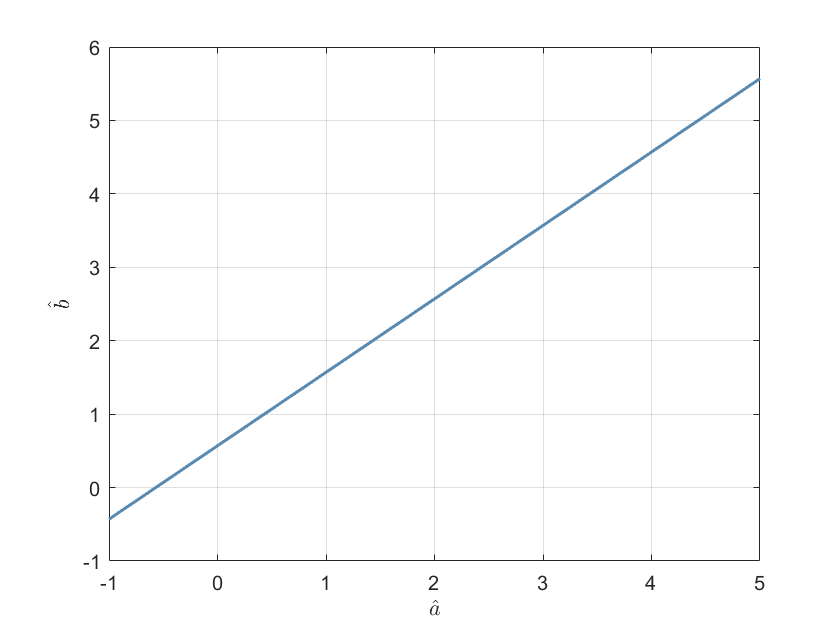

ex10_A

***Figura 3: ****Reta representante da relação entre *$a$ e $b$ para $\hat{\theta}$*.*

#### B) Ganho variável

Com o intuito de garantir $U>0$, pode-se realimentar $u(t)=-k(t)y(t)$ para $k(t)$ um ganho variável ou aumentar a ordem da realimentação para $u(t)=-k_1y(t)-k_2y(t-1)$. Para:


$$k\left(t\right)=\left\lbrace \begin{array}{ll}
k_1 \;, & t\le 5\\
k_2 \;, & t>5
\end{array}\right.$$


a reta $b(a)$ está ilustrada na Figura 4. Como as retas para $k_1$ e $k_2$ são referentes aos mesmos parâmetros $\hat{b}$ e $\hat{a}$, o ponto de intersecção entre as retas indica unicamente os valores de $a+k\alpha=1.5$ e $b-\alpha=1$. Se $k=1$e $\alpha=0.5$, obtém-se $b=1.5$ e $a=1$.

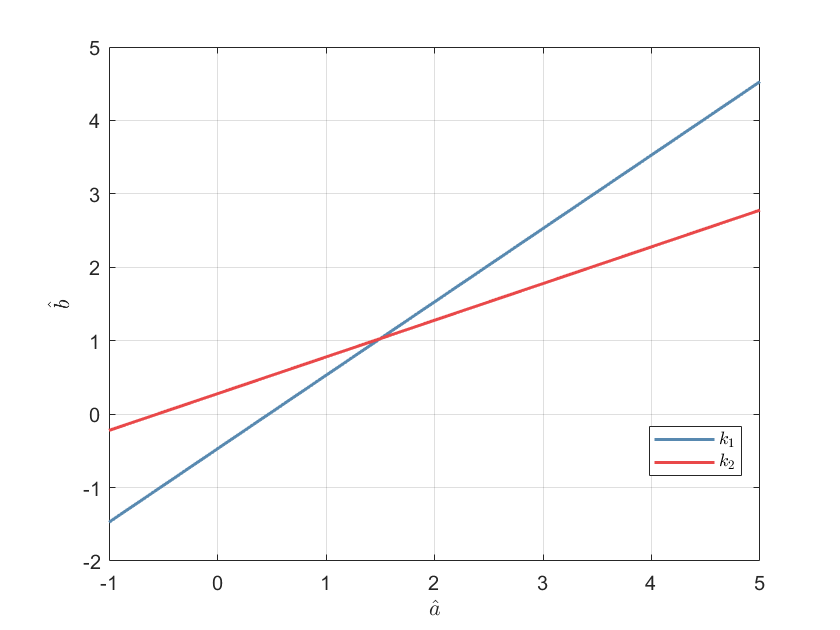

ex10_B

***Figura 4: ****Reta representante da relação entre *$a$ e $b$ para $\hat{\theta}$ com ganho de realimentação variável*.*

### Exemplo 12: Mudança de sinal de excitação

Considere o sistema $y(t)+ay(t-1) = bu(t-1)+e(t)+ce(t-1)$ para $a=-0.8$, $b=0.5$ e $e(t)$ um ruído branco gaussiano de média nula e variância $0,5$. Além disso,  $c=0$, $P(0)=100I$ e $\hat{\theta}(0)=0$. 

#### A) Pulso unitário

Para o RLS, é possível definir $\varphi(t-1) = [-y(t-1)\ u(t-1)]^T$ e $\hat{\theta}= [-a\ b]^T$. Considerando um sinal de excitação $u(t)$ como um pulso unitário em $t=50$ e um total de $n=1000$ amostras, obtém-se as estimativas para $a$ e $b$ conforme ilustrado na Figura 5.

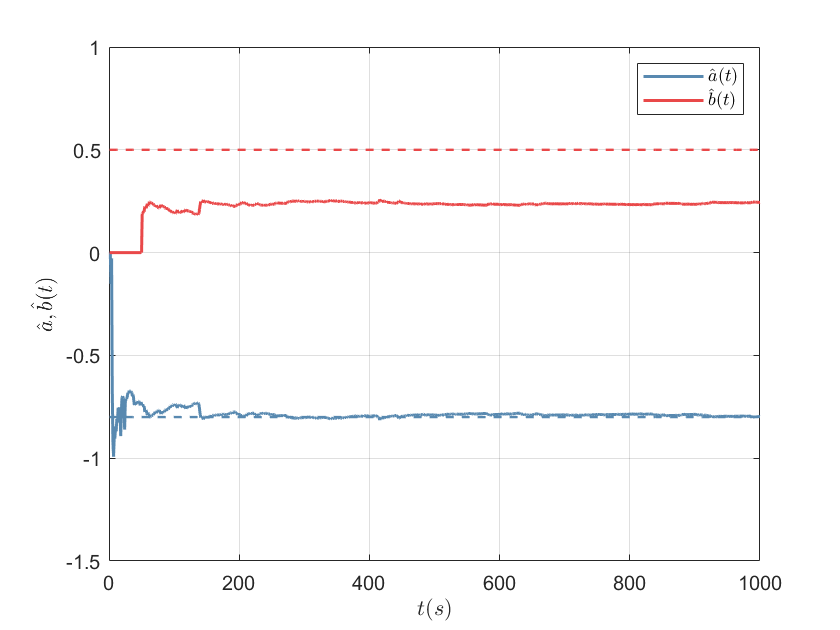

ex12_A

***Figura 5: ****Estimativas dos parâmetros *$\hat{b}$ e $\hat{a}$ em função do tempo empregando RLS para $u(t)$ um pulso*.*

Observando a Figura 5, é evidente que a estimativa do parâmetro $\hat{b}$ referente à entrada realimentada não acompanha o valor real $0,5$. Conforme discutido no Ex. 5, a função de excitação $u(t)$ pulso unitário não é persistente. 

#### B) Sinal periódico

Dessa forma, aplicou-se sobre o sistema uma entrada de onda quadrada $u(t)$ periódica com período $T=100$. As novas estimativas para $a$ e $b$ estão ilustradas na Figura 6.

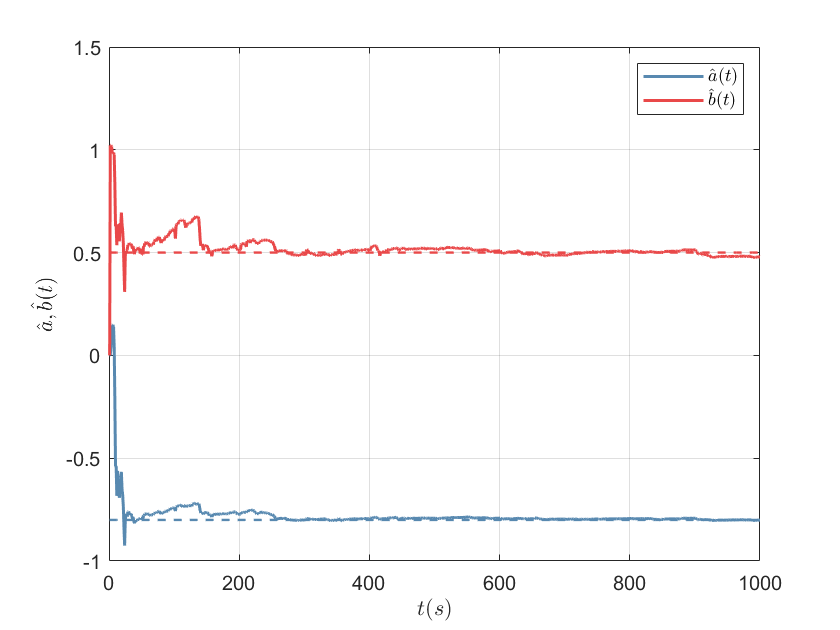

ex12_B

***Figura 6: ****Estimativas dos parâmetros *$\hat{b}$ e $\hat{a}$ em função do tempo empregando RLS para $u(t)$ uma onda quadrática*.*

Observando a Figura 6, é evidente que a estimativa do parâmetro $\hat{b}$ referente à entrada realimentada acompanha o valor real $0,5$. Conforme discutido no Ex. 5, a função de excitação $u(t)$ pulso unitário não é persistente para qualquer ordem $n=100$. O desvio padrão entre as estimativas $\hat{a}$ e $\hat{b}$ de seus valores reais são, respectivamente:

sqrt(mean((theta-ones(size(theta)).*[-0.8;0.5]).^2,2))

ans =     0.0863
    0.0613


Para simplificar a computação de uma nova matriz $P$ e $\hat\theta$ a cada amostra, pode-se empregar o algoritmo de aproximação de Kaczmarz, o qual considera:


$$K(t) = \frac{\gamma\varphi(t)}{\alpha+\varphi^T(t)\varphi(t)}$$


Determinando $\gamma=0.025$ e $\alpha=0.01$, encontra-se na Figura 7 estimativa para os parâmetros $a$ e $b$ com o método RLS.

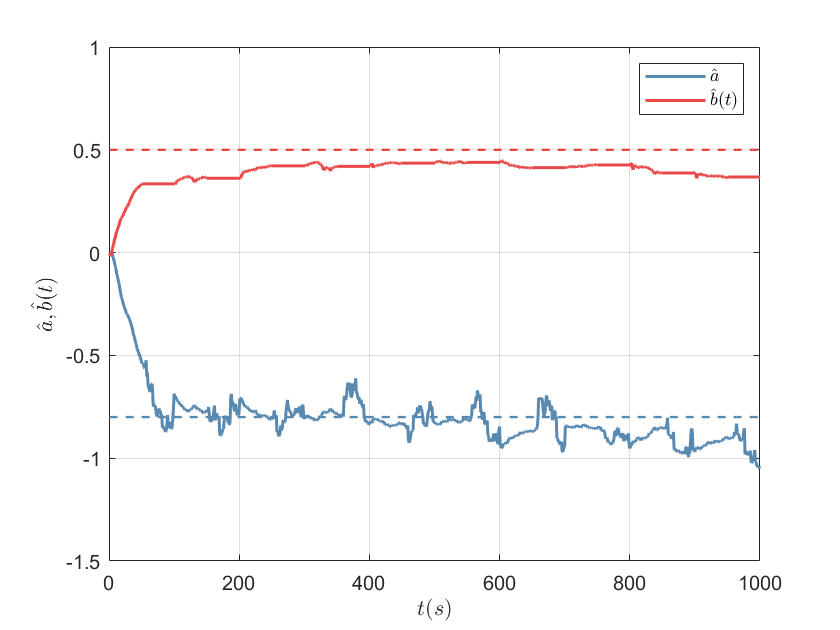

ex12_C

***Figura 7: ****Estimativas dos parâmetros *$\hat{b}$ e $\hat{a}$ em função do tempo empregando RLS para $u(t)$ uma onda quadrática com a aproximação de Kaczmarz*.*

Observando a Figura 7, é evidente que a simplificação do algoritmo minimiza a precisão da estimação. Uma maior eficiência do algoritmo poderia ser encontrada para diferentes valores de $\gamma$ e $\alpha$.

### Exemplo 13: Estimativa do erro

#### A) RLS

Agora, considera-se o sistema apresentado no Ex.12 com $c\neq 0$. Como o ruído modelado $e(t)+ce(t-1)$não é mais gaussiano com média zero, o desenvolvimento apresentado no Ex. 1 para $E\tilde{\theta}= 0$ não é mais válido. Aplicando o método RLS sobre o sistema, obtém-se as estimativas de $a$ e $b$ conforme apresentado na Figura 8.

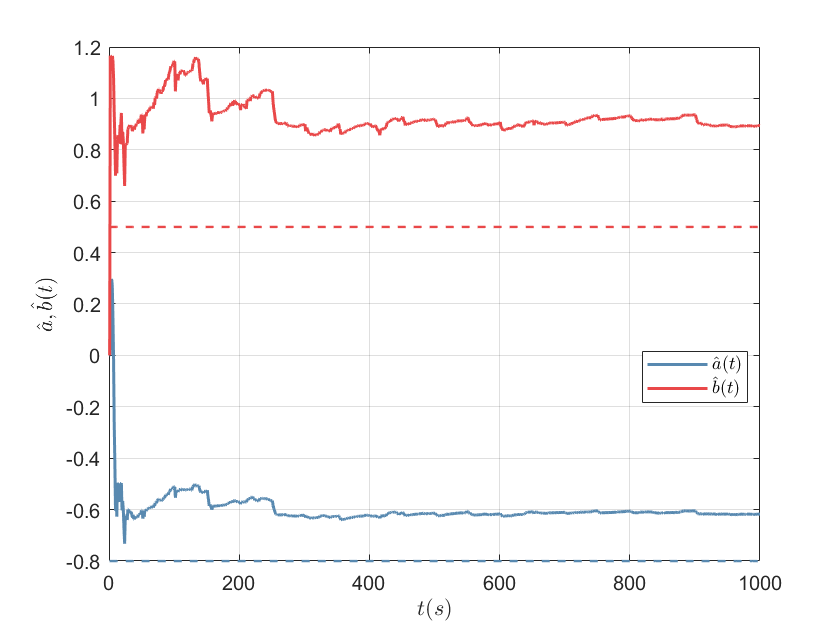

ex13_A

***Figura 8: ****Estimativas dos parâmetros *$\hat{b}$ e $\hat{a}$ em função do tempo empregando RLS para $u(t)$ uma onda quadrática e $c\neq 0$*.*

Observando a Figura 8, é evidente que por $E\tilde{\theta}\neq 0$, a estimativa dos parâmetros $\theta$ é enviesada. 

#### B) ELS

Para solucionar esse problema, pode-se aplicar a metodologia dos mínimos quadrados estendido (ELS), ou seja, para casos em que $E\varphi^T(t)e(t) \neq 0$. No ELS, considera-se o vetor 


$$\varphi(t-1) = [-y(t-1)\ ...\ -y(t-n)\ u(t-1)\ ...\ u(t-n)\ \varepsilon(t-1)\ ...\ \varepsilon(t-n)]^T$$


para $\varepsilon = y(t)-\varphi^T(t)\hat{\theta}(t-1)$, conforme discutido no Ex. 3. Dessa forma, considera-se $y(t)=\varphi^T(t-1)\theta_0+e(t)$. Aplicando o método ELS sobre o sistema, obtém-se as estimativas de $a$ e $b$ conforme apresentado na Figura 9.

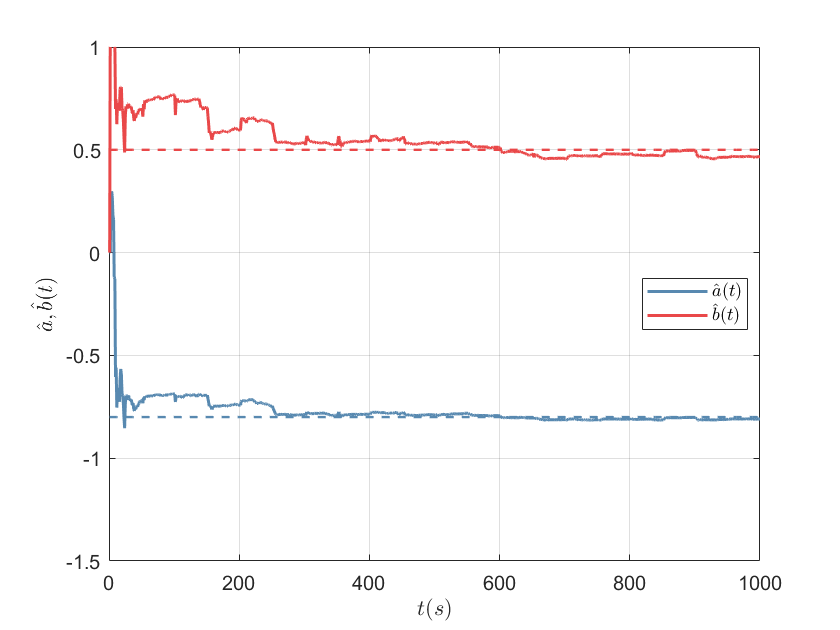

ex13_B

***Figura 9: ****Estimativas dos parâmetros *$\hat{b}$ e $\hat{a}$ em função do tempo empregando ELS para $u(t)$ uma onda quadrática e $c\neq 0$*.*

Observando a Figura 9, é evidente que a estimativa do parâmetro $\hat{b}$ referente à entrada realimentada acompanha o valor real $0,5$. O desvio padrão entre as estimativas $\hat{a}$ e $\hat{b}$ de seus valores reais são, respectivamente:

sqrt(mean((theta-ones(size(theta)).*[-0.8;0.5;-0.5]).^2,2))

ans =     0.0984
    0.1143
    0.1438


O desvio padrão para 1000 amostras é maior para o ELS que para o RLS quando $c=0$. Considerando no primeiro caso deve-se ajustar um parâmetro a mais que no último, é evidente que a estabilidade da estimativa no ELS será atingida com maior número de amostras em relação ao RLS.

### Exemplo 19: Parametrização de um circuito

Para estimar parâmetros em sistemas de tempo contínuo, é possível empregar LS para ajustar os coeficientes da função de transferência $G(s)$ do processo. Considerando que essa função de transferência descreve, no domínio do tempo, a seguinte relação entre entrada e saída:


$$\frac{d^ny}{dt^n} + a_1\frac{d^{n-1}y}{dt^{n-1}} + ... + a_ny = b_1\frac{d^{n-1}u}{dt^{n-1}}+b_nu$$
  

é possível reescrever a relação entre $y(t)$ e $u(t)$ como $A(p)y(t) = B(p)u(t)$, para $A(p)$ e $B(p)$ polinômios em função do operador diferencial $p=\frac{d}{dt}$. Analogamente à relação entre $y(t)$ e $u(t)$ apresentada na Fund. Teórica, é possível escrever os vetores:

$\varphi^T(t) = [-p^{n-1}y_f\ ...\ -y_f\ p^{n-1}u_f\ ...\ u_f]$ e $\theta^T = [a_1\ ...\ a_n\ b_1\ ...\ b_n]$

para $y_f(t)=H_f(p)y(t)$ e $u_f(t)=H_f(p)u(t)$, no qual $H_f$ é um filtro estável com excesso de polos responsável pela rejeição dos ruídos da operação derivada. 

Para esse exemplo, considere o sistema contínuo determinado pelo espaço de estados:


$$\dot{x} =$$

$$\left\lbrack \begin{array}{cc}
0 & -\frac{1}{C}\\
\frac{1}{L} & -\frac{R}{L}
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
\frac{1}{C}\\
0
\end{array}\right\rbrack u$$



$$y=\left\lbrack \begin{array}{cc}
0 & R
\end{array}\right\rbrack x$$


A função de transferência desse sistema pode ser escrita como 


$$G(s)=\frac{\theta_1\theta_2\theta_3}{s^2+\theta_1\theta_2s+\theta_2\theta_3}$$
 

para $\theta_1=R$, $\theta_2=1/L$ e $\theta_3=1/C$. Considerando $k_1=\theta_1\theta_2\theta_3$, $k_2=\theta_1\theta_2$ e $k_3=\theta_2\theta_3$, é possível estimar o vetor $\theta=[k_2\ k_3\ k_1]^T$ para $\varphi^T(t-1) = [-dy(t-1)/dt\ -y(t-1)\ u(t-1)]$.   Discretizando $G(s)$ com período de amostragem $h$, obtém-se a função de transferência:


$$H(q) = \frac{b_1q+b_2}{q^2+a_1q+a_2}$$


Dessa forma, pode-se considerar $\varphi^T(t-1) = [-y(k-1)\ -y(k-2)\ u(k-1)\ u(k-2)]$ e $\theta^T = [a_1\ a_2\ b_1\ b_2]$. Estimando os parâmetros da função de transferência discreta $H(q)$, obtém se a estimativa $\hat{y$ ilustrada na Figura 10.

The electrical initial states of your model are forced to zero by the powergui block.


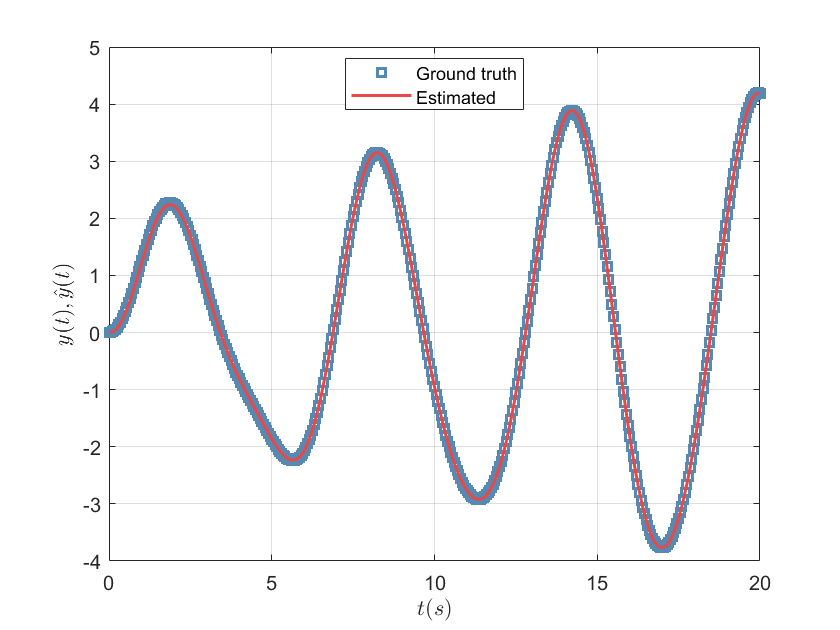

sim('../Simulink/ctlsea.slx')

***Figura 10: ****Estimativa *$\hat{y}$ e saída $y$ do espaço de estados do circuito.

A transformação de $H(q)$ em tempo discreto para $G(s)$ resulta na seguinte função de transferência:

gd=tf(numd,dend,h);
gc=d2c(gd)

gc =
 
  9.768e-12 s + 1
  ---------------
    s^2 + s + 1
 
Continuous-time transfer function.



Logo, comparando com o equacionamento de $G(s)$, conclui-se que $k_1=k_2=k_3=1$. Quaisquer valores de $R$, $L$ ou $C$ que obedeçam a esse equacionamento validam o sistema simulado.

### Exercício proposto 21: Variação de parâmetros do RLS

Para esse exercício, será considerado o sistema apresentado no Ex. 12B. 

#### A) Variação de $\hat{\theta}$

Ao variar o valor inicial de $\hat{\theta}(0)$, considerando $P(0)=I$, obtém-se o traçado para as estimativas $\hat{b}$ e $\hat{a}$ ilustrado na Figura 11.

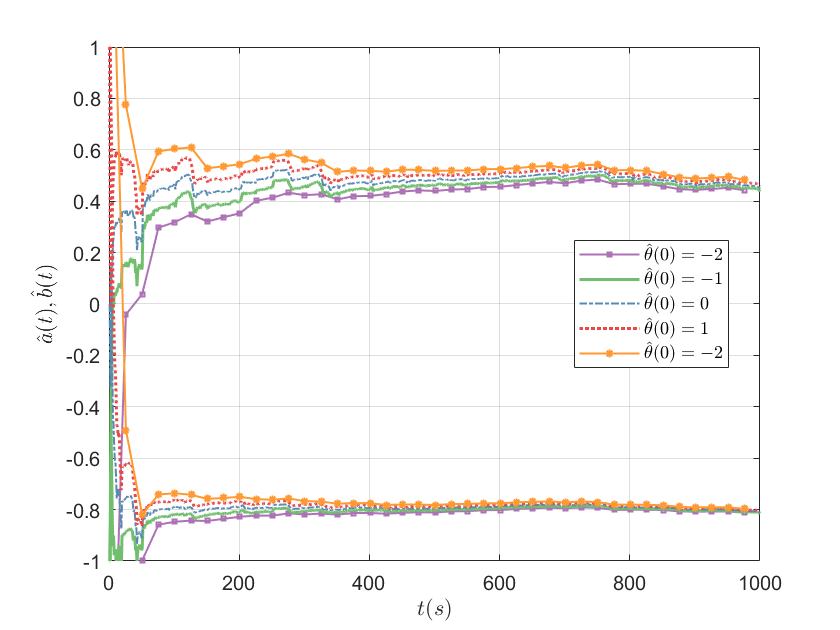

ex21_A

***Figura 11: ****Estimativa *$\hat\theta$ considerando a variação de $\hat{\theta}(0)$.

Observando a Figura 11, é evidente que a estimativa inicial de $\hat\theta(0)$ influencia os valores das primeiras amostras de $\hat\theta(t)$, tendo em vista que a atualização de $\hat{\theta}(t)$ em função de $\hat{\theta}(t+1)$ é uma soma. Entretanto, essa mudança não influencia a estimativa final de $\hat\theta(1000)$, uma vez que o algoritmo RLS é robusto e independe do valor de $\hat\theta(0)$.

#### B) Variação de $P(0)$

Ao variar o valor inicial de $P(0)$ considerando $\hat\theta(0)=0$, obtém-se o traçado para as estimativas $\hat{b}$ e $\hat{a}$ ilustrado na Figura 12.

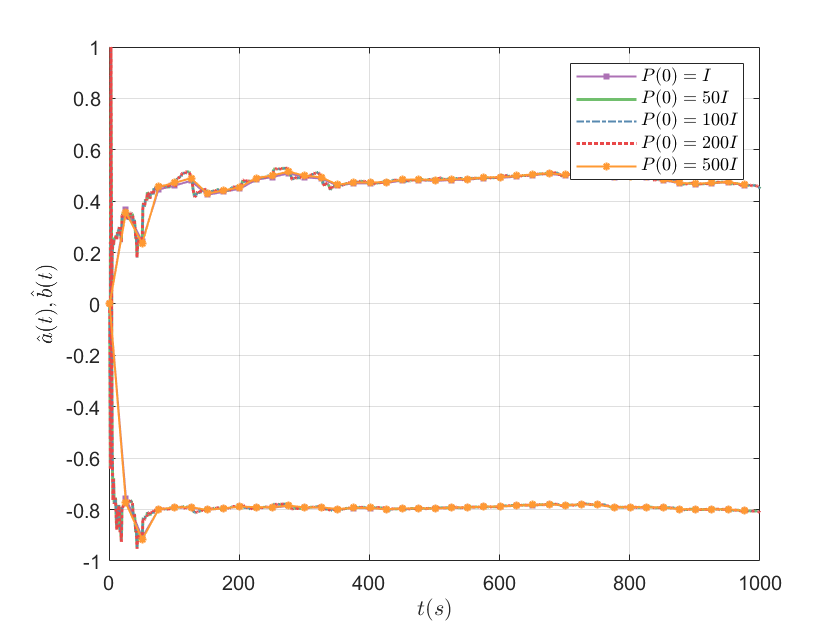

ex21_B

***Figura 12: ****Estimativa *$\hat\theta$ considerando a variação de $P(0)$.

Observando a Figura 12,  analogamente ao item A, é evidente que o valor inicial de $P(0)$ influencia os valores das primeiras amostras de $\hat\theta(t)$, tendo em vista que a atualização de $\hat{\theta}(t)$ em função de $\hat{\theta}(t+1)$ é uma soma. Entretanto, essa mudança não influencia a estimativa final de $\hat\theta(1000)$, uma vez que o algoritmo RLS é robusto e independe do valor de $P(0)
$. 

Comparando a Figura 11 com a Figura 12, é claro que a mudança de $\hat\theta(0)$ impacta mais nas amostras iniciais de $\hat{\theta}(t)$do que a variação de $P(0)
$. Esse fator é justificável por $K(t)\varepsilon(t) <<< \hat{\theta}(t-1)$ na equação de atualização de $\hat{\theta}(t)$.

#### C) Variação de $\lambda$

Para estimar parâmetros variantes no tempo, pode-se acrescentar à função de custo $V(\theta,t)$ um fator $\lambda$ de esquecimento das amostras, tal qual a seguinte formulação:


$$V(\theta,t)= \frac{1}{2}\sum_{k=1}^t \lambda^{t-k}\big(y(k)-\varphi^T(k)\theta\big)^2$$


para $0<\lambda\leq 1$. Dessa forma, quanto mais recente a amostra, isto é, quando maior $k$, maior será $\lambda^{t-k}$ e, consequentemente, o peso dessa amostra para o ajuste da estimativa $\hat\theta$.

Ao variar $\lambda$, obtém-se o traçado para as estimativas $\hat{b}$ e $\hat{a}$ ilustrado na Figura 13.

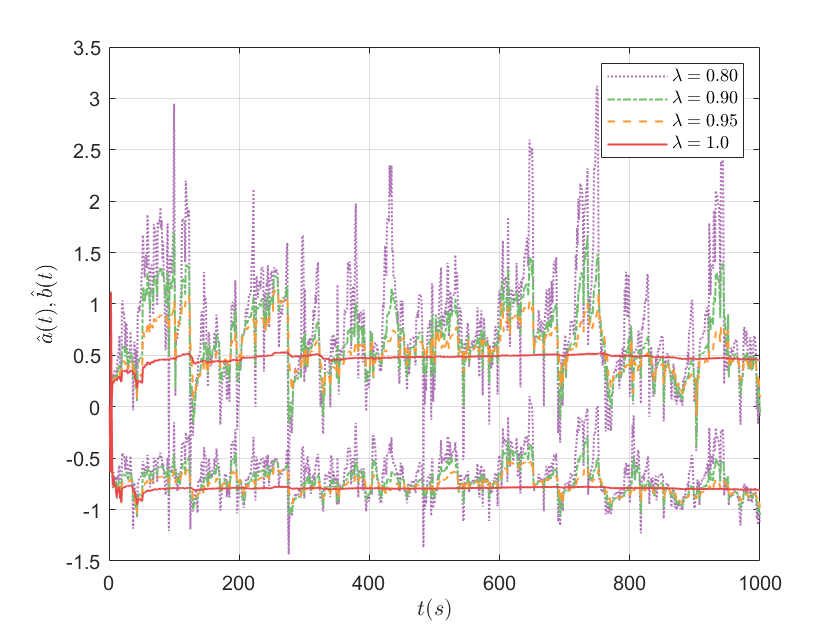

ex21_C

***Figura 13: ****Estimativa *$\hat\theta$ considerando a variação de $\lambda$.

Observando a Figura 13,  é evidente que quanto menor o $\lambda$, maior é o esquecimento do algoritmo e maior é a oscilação da estimativa. Dessa forma, conclui-se que esse método é adequado apenas para processos cujos parâmetros são variantes no tempo, o qual não é o caso da questão proposta. Uma forma de minimizar a oscilação seria diminuir o período do sinal de excitação, em razão do aumento da variação da resposta $y(t)$.

#### D) Variação de $T$

Ao variar o período $T$, obtém-se o traçado para as estimativas $\hat{b}$ e $\hat{a}$ ilustrado na Figura 14.

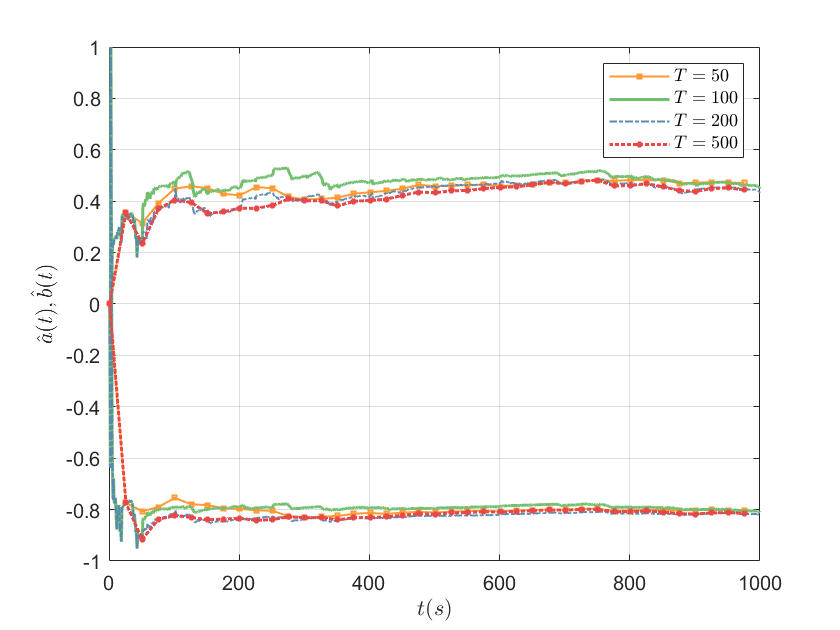

ex21_D

***Figura 14: ****Estimativa *$\hat\theta$ considerando a variação de $T$.

Observando a Figura 14,  é evidente que quanto menor o $T
$, maior é a oscilação da estimativa. Tendo em vista a menor regularidade do processo com a redução do período, mais difícil é o ajuste do vetor $\hat\theta$ tendo em vista a mudança do sinal de $K(t)\varepsilon(t)$.

## **Referências bibliográficas**

[1] L. LJUNG. **Introduction**. Courier Corporation, 2008. ISBN 9780748408788.

[2] K. ASTRÖM, B. WITTENMARK. **Real-time Parameter Estimation**. CRC Press, 2000. ISBN 0486462781.